# Reduced system: time course

time = 4000;
dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

Iattn = 0.02;

Delta_E = 0.1475;
Delta_I = 0.01175;
ratio_sens_attn = 12;

[r,~,~] = SandA_reduce_L6(Delta_E, Delta_I, Iattn, time);
r = r*1000;

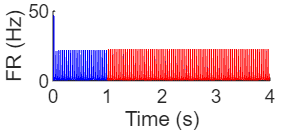

pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax(1:100000),squeeze(r(pop,1:100000,4)),'r','LineWidth',0.5);
plot(timeax(1:100000),squeeze(r(pop,1:100000,5)),'b','LineWidth',0.5);
plot(timeax(100001:400000),squeeze(r(pop,100001:400000,5)),'b','LineWidth',0.5);
plot(timeax(100001:400000),squeeze(r(pop,100001:400000,4)),'r','LineWidth',0.5);

hold off;
% axis([0 4 20.6 20.9]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L23E');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

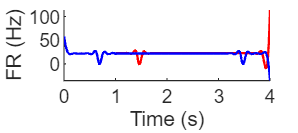

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
% axis([0 4 20.6 20.9]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L23E_env');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

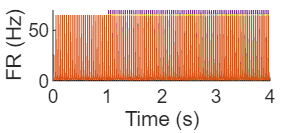

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.5);

hold off;
% axis([0 4 120 145]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L5E');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

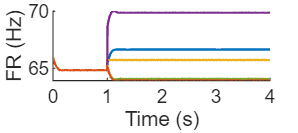

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
% axis([0 4 120 145]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L5E_env');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');